**Exercise 1**

Use


$$(a+b)^n = \sum_{k = 0}^n \binom{n}{k} a^k b^{n-k}$$


to show that the binomial distribution fulfils the second axiom of probability, i.e. $B(n; n,p) = 1$.

From the Lecture we have the result:


$$B\left(x;n,p\right)=\sum_{k=0}^x {\left({{n}\atop{k}}\right)}p^k {\left(1-p\right)}^{n-k}$$


So for $x=n$ we get


$$B\left(n;n,p\right)=\sum_{k=0}^n {\left({{n}\atop{k}}\right)}p^k {\left(1-p\right)}^{n-k}$$


Now we use $(a+b)^n = \sum_{k = 0}^n \binom{n}{k} a^k b^{n-k}$ to get


$$B\left(n;n,p\right)={\left(p+\left(1-p\right)\right)}^n =1^n =1$$


Q.E.D.

**Exercise 2**

Use MATLAB (or what you prefer) to plot a probaility bar chart of $b(x;50,0.2)$ and $b(x;50,0.8)$. The relevant function for MATLAB is `binopdf()`.

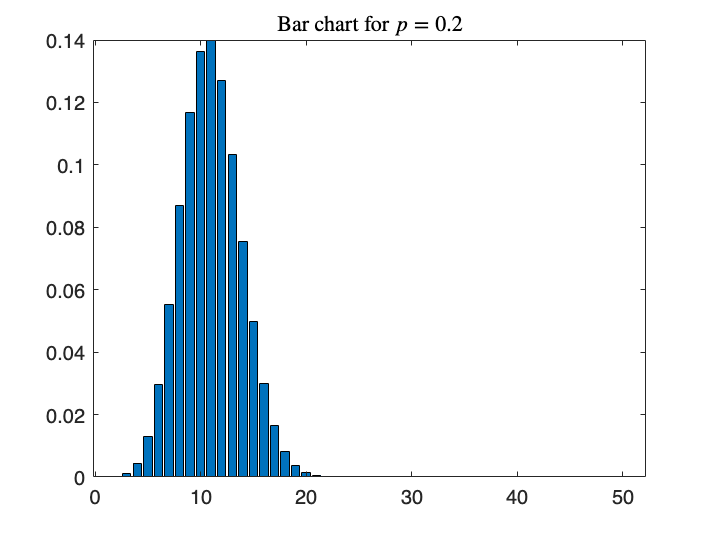

n = 50; %number of trials

x = 0:n;

p1 = 0.2; %propability 1
p2 = 0.8; %probability 2

b1 = binopdf(x,n,p1);
b2 = binopdf(x,n,p2);

bar(b1)
title("Bar chart for $p = 0.2$", "interpreter", "latex")

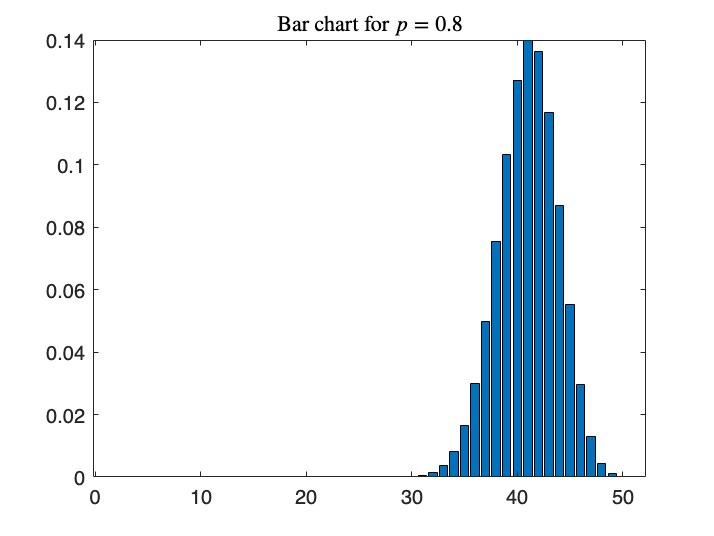


bar(b2)
title("Bar chart for $p = 0.8$", "interpreter", "latex")

**Exercise 3**

Use MATLAB (or what you prefer) to generate 100 random numbers from a random variable $X$ having a $b(x;50,0.2)$ distribution and plot a histogram of the random numbers. Repeat the exercise for 1000 random numbers. Comment on your result. The relevant function for MATLAB is `binornd()`.

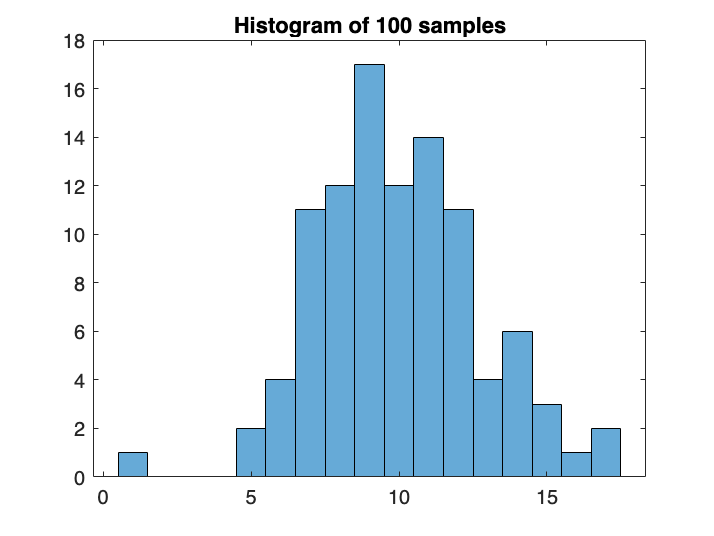

n = 50;  %Number of trials per experiment
p = 0.2; %Success chance for each experiment

%100 simulations
X100 = binornd(n, p, [100, 1]);
figure;
histogram(X100);
title("Histogram of 100 samples")

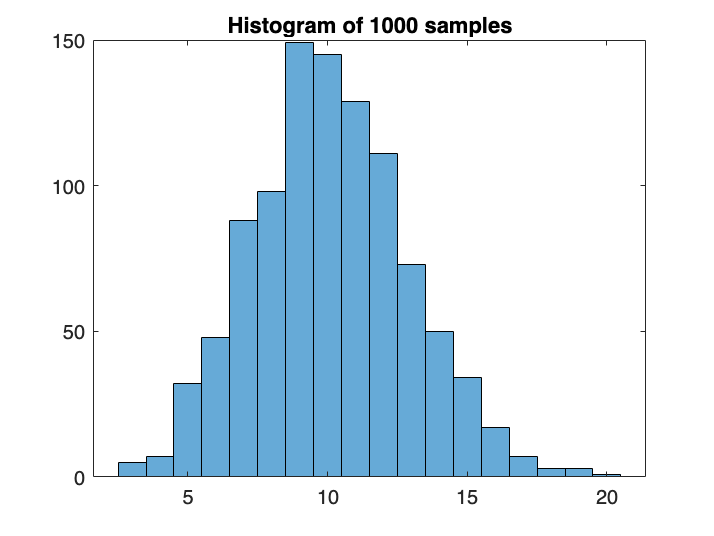


%1000 simulations
X1000 = binornd(n, p, [1000, 1]);
figure;
histogram(X1000);
title("Histogram of 1000 samples")

We note that the result becomes less noisy for $x = 1000$ simulations than for $x = 100$ simulations

**Exercise 4**

Let $X$ be a random variable with binomial distribution $b(x;n,p)$. Use the formulae for the mean and the variance to show that

$E(X^2) = np (1 -p) + n^2 p^2$.

We have that the mean for a binomial distribution is $\mu =E\left(X\right)$ and the variance is

 
$$\sigma {\;}^2 =\sum_{\mathrm{all}\;x} {\left(x-\mu \;\right)}^2 f\left(x\right)\;$$


Expanding the square here gives

 
$$\sigma {\;}^2 =\sum_{\mathrm{all}\;x} \left(x^2 +\mu {\;}^2 -2x\mu \;\right)f\left(x\right)\;=\sum_{\mathrm{all}\;x} x^2 f\left(x\right)+\mu {\;}^2 \sum_{\mathrm{all}\;x} f\left(x\right)-2\mu \;\sum_{\mathrm{all}\;x} x\;f\left(x\right)\;$$


We know that $\sum_{\mathrm{all}\;x} x^2 f\left(x\right)=E\left(X^2 \right)$, $\sum_{\mathrm{all}\;x} f\left(x\right)=1$ and $\sum_{\mathrm{all}\;x} \;x\;f\left(x\right)=E\left(X\right)$. Hence


$$\sigma {\;}^2 =E\left(X^2 \right)+\mu {\;}^{2\;} -2\mu \;E\left(X\right)\;$$


We know that $E(X) = \mu$ hence, solving for $E(X^2)$ we get


$$E\left(X^2 \right)=\mu {\;}^2 +\sigma {\;}^2$$


We know $\mu = np$ and $\sigma^2 = np(1-p)$, so


$$E\left(X^2 \right)=n^2 p^2 +n\;p\;\left(1-p\right)$$


**Exercise 5**

Let $X$ be a discrete random variable with probability distribution $f(x)$ and mean $\mu$ and variance $\sigma^2$. Find the mean and variance of $Z = aX + b$, where $a$ and $b$ are constants.

For the mean we use that


$$E\left(Z\right)=E\left(a\;X+b\right)=a\;E\left(X\right)+b=a\;\mu +b$$


For the variance we start from the definition


$$\mathrm{Var}\left(Z\right)=E\left({\left(Z-E\left(Z\right)\right)}^2 \right)$$



$$\mathrm{Var}\left(Z\right)=E\left({\left(\mathrm{aX}+b-a\;\mu -b\right)}^2 \right)$$



$$\mathrm{Var}\left(Z\right)=E\left({\left(\mathrm{aX}-a\mu \;\right)}^2 \right)$$



$$\mathrm{Var}\left(Z\right)=E\left(a^2 {\left(X-\mu \;\right)}^2 \right)=a^2 {E\left(X-\mu \;\right)}^2 =a^2 \mathrm{Var}\left(X\right)=a^2 \sigma {\;}^2$$


Hence, $E(Z) = a\mu + b$ and $Var(Z) = a^2 \sigma^2$.

**Exercise 6**

Consider the experiment of tossing a fair coin twice. Let $X$ be the number of heads. Calculate the mean and variance of $X$ and $Z=x^2$.

We let X be the number of heads, with $X \in \{0, 1, 2\}$, with


$$P(X=0) = 1/4, \quad P(X=1) = 1/2, \quad P(X=2) = 1/4$$


Our mean is then


$$E(X) = 0 \cdot 1/4 + 1 \cdot 1/2 + 2 \cdot 1/4 = 1$$


And our second moment is


$$E(X^2) = 0^2 \cdot 1/4 + 1^2 \cdot 1/2 + 2^2 \cdot 1/4 = 3/2$$


Hence, our variance is


$$Var(X) = E(X^2) - E(X)^2 = 3/2 - 1^2 = 1/2$$


For Z we get $Z \in \{0, 1, 4\}$, with


$$P(X=0) = 1/4, \quad P(X=1) = 1/2, \quad P(X=4) = 1/4$$


Our mean is then


$$E(X) = 0 \cdot 1/4 + 1 \cdot 1/2 + 4 \cdot 1/4 = 3/2$$


And our second moment is


$$E(X^2) = 0^2 \cdot 1/4 + 1^2 \cdot 1/2 + 16 \cdot 1/4 = 9/2$$


Hence, our variance is


$$Var(X) = E(X^2) - E(X)^2 = 9/2 - 9/4 = 9/4$$


**Exercise 7**

Generate $n = 2, 4, 8, 16, 32, 64, 128, 256, 512, 1024$ random numbers from a random variable $X$ having a $b(x; 50, 0.2)$ distribution. Use these samples and plot the sample mean and sample variance as a function of $n$. Use a logarithmic scale on the $n$ axis. Also indicate the mean and variance of $X$ for comparison. Comment on your results. Relevant functions in MATLAB are `mean()` and `var()`. 

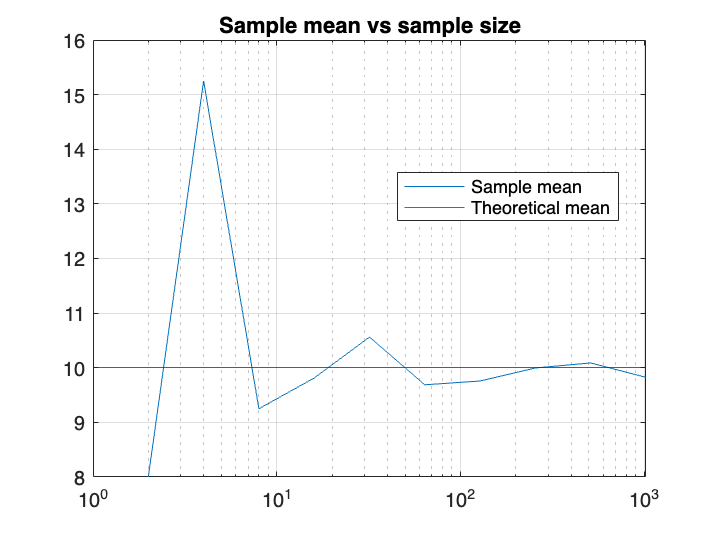

clear; close all; clc;

N = 50; % trials in Bin(N,p)
p = 0.2;

% Sample sizes
n_list = 2.^(1:10);

m_hat = zeros(size(n_list));
v_hat = zeros(size(n_list));

% Theoretical values
mu = N*p;
sigma2 = N*p*(1-p);

for i = 1:numel(n_list)
    n = n_list(i);
    X = binornd(N, p, [n, 1]); % n samples from Bin(N,p)
    m_hat(i) = mean(X);
    v_hat(i) = var(X);         % sample variance (normalizes by n-1)
end

% Plot sample mean vs n
figure;
semilogx(n_list, m_hat); hold on;
yline(mu);
grid on;
title('Sample mean vs sample size');
legend('Sample mean','Theoretical mean','Location','best');

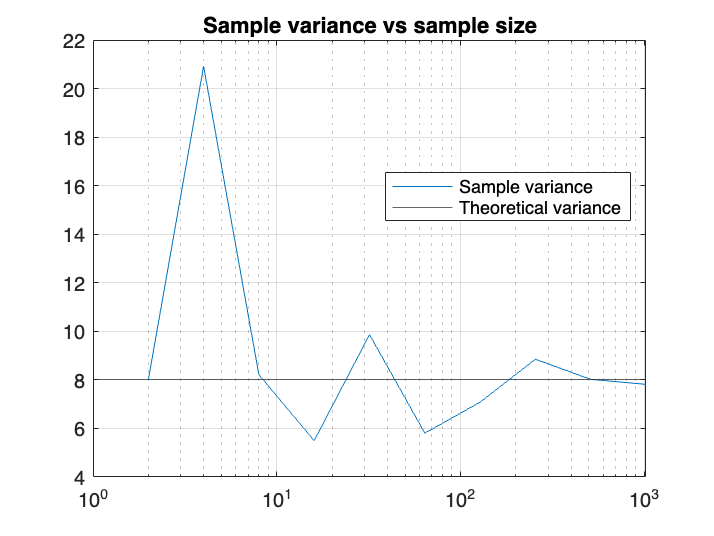


% Plot sample variance vs n
figure;
semilogx(n_list, v_hat); hold on;
yline(sigma2);
grid on;
title('Sample variance vs sample size');
legend('Sample variance','Theoretical variance','Location','best');